clear all

% This makes the PM2Pixel transform based on a cartesian grid of points.
% Use this to make Hi-res grid used in TM_reconstruction5, with ShrinkPix
% set to 1.

%% addpath('/Users/Dave/Work/Exeter/Projects/MMF mode calculator/functions');

shrinkPix = 0; % if shrinkPix = 1 then reduce the number of pixels to just those representing the field in the core
% set shrinkPix to 1 for PM2Pix2 (big) and set PM2Pix to 0 for PM2Pix
% (small).

index1 = 20;

Width = 31; %61; ;%61; %121; % MAKE SURE ODD
Centre = (Width-1)/2 + 1; % or enter your own choice
CoreRadPix = 15; %30; %30; %55;
manualRes = [CoreRadPix,Centre,Centre,Width,Width];
%radius, rowCOM, colCOM, imHeight, imWidth; all in pixels
save('manualRes.mat','manualRes');


fibreData = dlmread('uwlm.txt');

% Just crop to the first few modes for texting
%fibreData = fibreData(1:10,:);

[N_modes, ~] = size(fibreData);
N_modes = N_modes-1; % reduce the count by one to account ofr first line being fibre Params.
Params = fibreData(1,:);
a = Params(1); % core radius (um)
NA = Params(2); % NA
n_c = Params(3); % refractive index of core
lam = Params(4); % wavelngth (um)

uwlm = fibreData(2:N_modes+1,:);

## fibre parameters

%a = 50; %12.5;
a_std = a*1e-6;
%NA = 0.22; %0.22;
%n_c = 1.4570;
n_out = (n_c^2 - NA^2)^0.5;
%n_clad = ; % refractive index of cladding
%NA = (n_core^2 - n_clad^2)^0.5;
%N = 50; % Fibre mode plots are 2N+1 by 2N+1 pixels (therefore middle pixel is origin) %%8
%scaling = 1.5; % scaling is the factor of how many core widths fit across the cartesian grid

## wavelength

%lam = 0.633;
%lam = 0.633; % wavelength (um)
lam_std = lam*1e-6;
k = 2*pi/lam;
k_std = 2*pi/lam_std;
v = a*k*NA; % vnumber (i.e. normalised frequency) of fibre
k_stdn_c = k_std*n_c;

## Generate complex array representing the spatial profile of each mode in the fibre

ResData = manualRes;

coreDiameterInPixels = ResData(1)*2;
pad = floor(floor(coreDiameterInPixels)/8); %0;
%Pad increases the size of the plot box so that when normalised it
%captures power in cladding. It then reduces back to original
%pre-padded size before constructing the transfer matrix
pixPitch = (2*a)/coreDiameterInPixels; % pixel pitch in um
rowCoM = ResData(2)+pad;
colCoM = ResData(3)+pad;
Npix1D = ResData(4)+2*pad;
pixVec = 1:1:Npix1D;
xVec = (pixVec - colCoM)*pixPitch;
yVec = (pixVec - rowCoM)*pixPitch;

[x,y]=meshgrid(xVec,yVec); % check these are the correct way around
r=abs(x+1i*y);
psi=angle(x+1i*y);
M=heaviside(a-r);

F = zeros(Npix1D,Npix1D,N_modes);
Beta = zeros(N_modes,1);
F = complex(F,F);
for n=1:1:N_modes
    index = n;
    u = uwlm(index,1); % No need to renormalise u or v as the length dimesnion cancels
    w = uwlm(index,2);
    l = uwlm(index,3);
    m = uwlm(index,4);

    part1 = k_std^2*n_c^2;
    part2 = u^2/a_std^2;
    Beta(index) = (part1 - part2)^0.5;

    F(:,:,n) = (besselj(l,u*r/a)./besselj(l,u).*exp(1i*l*psi).*M) + besselk(l,w*r/a)./besselk(l,w).*(1-M).*exp(1i*l*psi);

    if l~=0
        % correct for NaNs at centre of modes where l~=0
        F((Npix1D+1)/2,(Npix1D+1)/2,n) = 0;
    else
        % correct for NaNs at centre of modes where l=0
        F((Npix1D+1)/2,(Npix1D+1)/2,n)=F((Npix1D+1)/2 -1,(Npix1D+1)/2,n);
    end
save('Beta.mat', 'Beta')
end

## Normalise modes

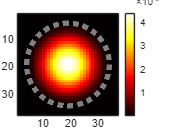

F2 = zeros(Npix1D-2*pad,Npix1D-2*pad,N_modes);
F2 = complex(F2,F2);
for q=1:size(F,3)
    F(:,:,q)=F(:,:,q)./sqrt(sum(sum(abs(F(:,:,q)).^2))); % normalise mode
    % now crop mode by removing pad pixels
    F2(:,:,q)=F(pad+1:Npix1D-pad,pad+1:Npix1D-pad,q);
end


FF=reshape(F2,[size(F2,1)*size(F2,2),size(F2,3)])';

%Check padded figures
AmpFigCircle1(abs(F(:,:,index1)).^2,coreDiameterInPixels,colCoM,rowCoM);

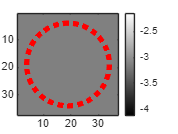

PhaseFigCircle1(angle(F(:,:,index1)),coreDiameterInPixels,colCoM,rowCoM);

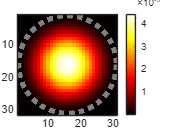


% now redefine resolution variables without the padding
rowCoM = ResData(2);
colCoM = ResData(3);
Npix1D = ResData(4);

% Create figures
AmpFigCircle1(abs(F2(:,:,index1)).^2,coreDiameterInPixels,colCoM,rowCoM);

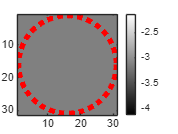

PhaseFigCircle1(angle(F2(:,:,index1)),coreDiameterInPixels,colCoM,rowCoM);


save('Modes.mat','F2')

## Functions

function AmpFigCircle1(data,coreDiameterInPixels,cxPix,cyPix)

% [N, M] = size(data);
% N = (N-1)/2;
% M = (M-1)/2;


% Create figure
figure1 = figure('Color',[1 1 1]);
colormap('hot');

% Create axes
axes1 = axes('Parent',figure1);

% Create image
image(data,'Parent',axes1,'CDataMapping','scaled');
hold on

% create circle data
noOfThetaSteps = 100;
TStep = 2*pi/noOfThetaSteps;
circAngle = 0:TStep:2*pi;
circRadius = zeros(1,noOfThetaSteps+1) + coreDiameterInPixels/2;
cxCoords = circRadius.*cos(circAngle);
cyCoords = circRadius.*sin(circAngle);

plot(cxCoords+cxPix,cyCoords+cyPix,'Parent',axes1,'LineWidth',4,'LineStyle',':',...
    'Color',[0.5 0.5 0.5]);

% Create colorbar
colorbar('peer',axes1);
axis equal
axis tight
end

function PhaseFigCircle1(data,coreDiameterInPixels,cxPix,cyPix)

data = mod(data,2*pi)-pi;

% [N, M] = size(data);
% N = (N-1)/2;
% M = (M-1)/2;

% Create figure
figure1 = figure('Color',[1 1 1]);
colormap('gray');

% Create axes
axes1 = axes('Parent',figure1);

% Create image
image(data,'Parent',axes1,'CDataMapping','scaled');
hold on

% create circle data
noOfThetaSteps = 100;
TStep = 2*pi/noOfThetaSteps;
circAngle = 0:TStep:2*pi;
circRadius = zeros(1,noOfThetaSteps+1) + coreDiameterInPixels/2;
cxCoords = circRadius.*cos(circAngle);
cyCoords = circRadius.*sin(circAngle);

plot(cxCoords+cxPix,cyCoords+cyPix,'Parent',axes1,'LineWidth',4,'LineStyle',':',...
    'Color',[1 0 0]);

% Create colorbar
colorbar('peer',axes1);
axis equal
axis tight
end